# **변경사항**

## 2021년 11월 22일

첫 배포

# **주의**

## **(1) spike detection algorithm 관련**

저희가 사용하는 spike detection algorithm(`channel.detectSpikes`)은 CyborgBrainOrg.m에서 가져온 것인데, 이 코드는 threshold를 음수로 잡고 (threshold *  표준편차)보다 낮은 값이 발생하면 spike로  판단합니다. 이는 대부분 threshold를 양수로 잡아 spike를 정의하는 것과는 다른 정의입니다. 이 정의에 맞게 양수 (threshold *  표준편차)보다 큰 값을 spike로 판단하는 함수를 따로 만들었습니다(`channel.detectSpikesPositive`). 단, 한 channel object에서는 한 방법만 써야 합니다. 다른 방법을 쓰면 기존에 저장한 spike 정보가 지워집니다.

정원기 님이 특정 amplitude 이상의 spike만을 counting한다고 하셨는데, 이 작업에는 `detectSpikes보다 detectSpikesPositive가 더 적합할 수 있습니다. 아래 예제에서는 detectSpikes를 사용하였습니다.`

## (2) 경로 추가 관련

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

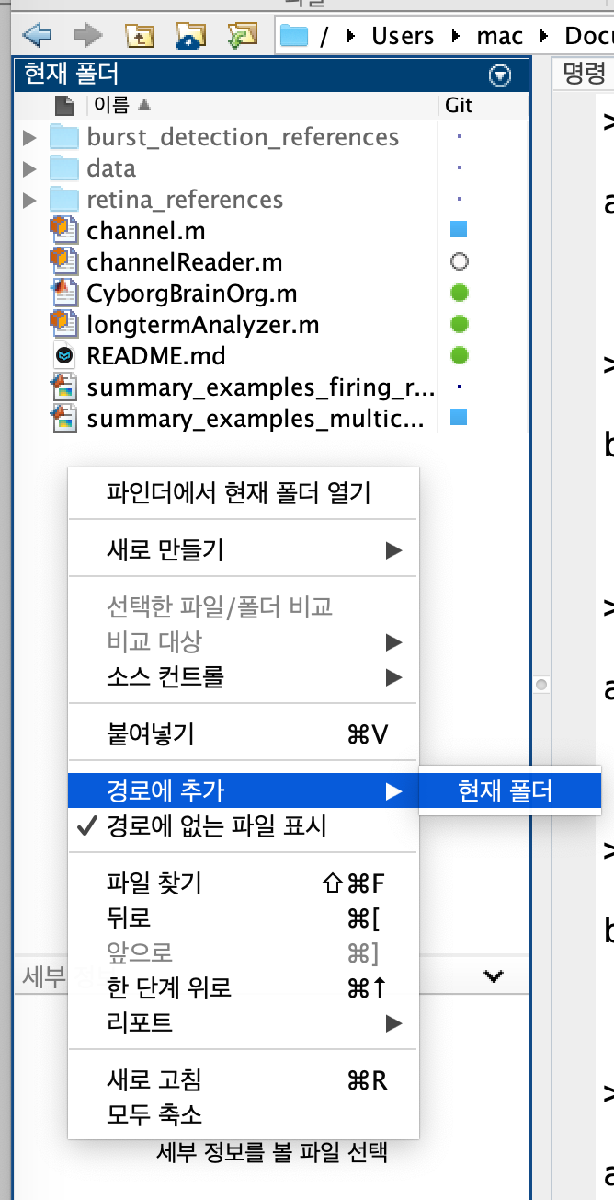

# **Peri-Stimulus Time Hitogram 코드 설명 및 예제**

정원기 님이 보내주신 wallisch2009를 참고하였습니다. 저희 데이터에 맞게 전처리하는 과정을 넣었고, 코드를 최대한 한 줄 한 줄 설명하였습니다.

Data 1.csv의 경우, 시간 정보가 없어서 0초부터 시작했다고 가정하고 sample rate를 이용해 시간 변수를 계산하였습니다.

Data 2.csv는 시간 정보가 있었기에 그대로 사용했습니다.

## (0) 데이터 로드 및 전처리

### **0.1. time variable이 없는 retina data 불러와 channel object 만들기**

reader = channelReader(); %channelReader object 생성
%                               % filename,     timeColumnIdx  startRowIdx  startColIdx    sampleRate     organoidNum   channelNum     month
data1 = reader.readSingleChannel("./data/Data 1.csv",      0,       8,             1,            3152,           1,              1,         1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
channel number = 1
sampling rate = 3152.000000Hz
starts at 0.000000, ends at 3.248414, duration = 3.248414
number of timestamps = 10240



### **0.2. time variable이 있는 retina data 불러와 channel object 만들기**

%                                    % filename,    timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum    month
data2 = reader.readSingleChannel("./data/Data 2.csv",      1,            8,             2,            nan,           1,            1,        1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
1행의 관측치 수가 1382로, 2048개인 다른 행보다 관측치 수가 적습니다.
channel number = 1
sampling rate = 24414.062313Hz
starts at 1.285571, ends at 81.369458, duration = 80.083887
number of timestamps = 1955174



### ** 0.3 bandpass filter preview**

channel object에서 raw 데이터를 불러와서 bandpass filter 적용시 어떤 결과가 나오는지 그래프로 확인

#### data 1.csv

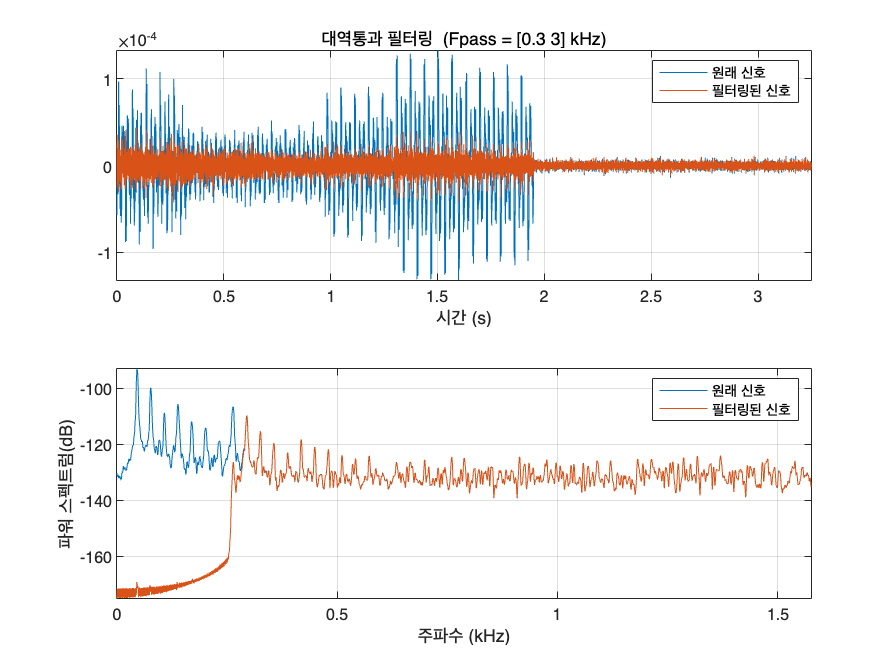

%apply bandpass filter 300-3000hz
bandpass(data1.raw, [300,3000], data1.sf)

#### data 2.csv

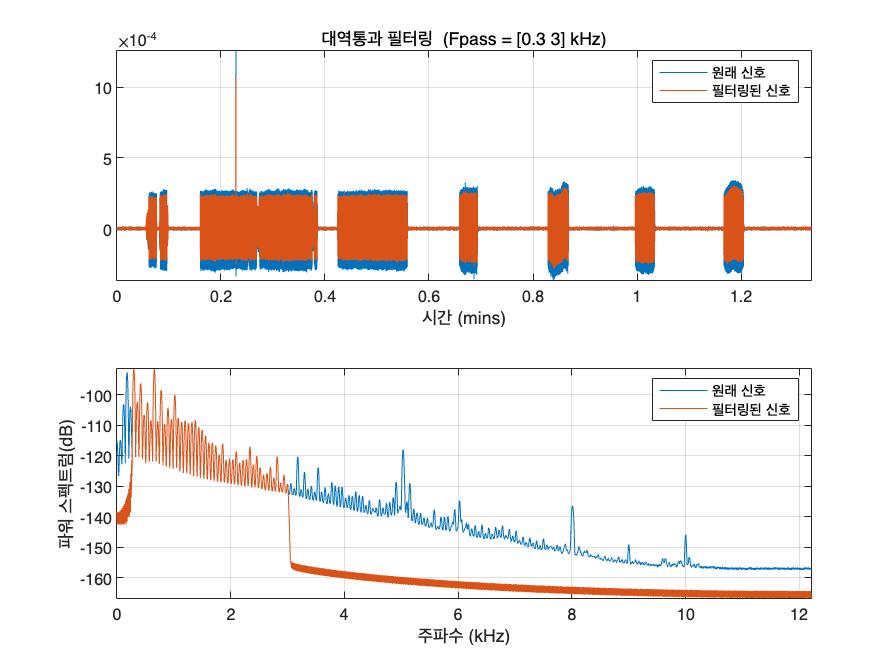

bandpass(data2.raw, [300,3000], data2.sf)

### **0.4. bandpass filter 적용**

**파라미터 1개 **

- `passBand` : [숫자, 숫자] 포맷으로, hz 단위로 입력

 bandpass filter 실제로 적용하여 channel object 내에 저장

data1.bandPass([300,3000]); %apply bandpass filter 300-3000hz

data2.bandPass([300,3000]); %apply bandpass filter 300-3000hz

### **0.5. (method) **`detectSpikes`

**spike detection 수행**

**paramter 3개**

- `thres`: spike 분류 기준. 5를 입력하면 평균+5표준편차 밖의 값을 spike로 분류 ((reference code에서는 5)

- `preTime`: spike waveform의 spike 앞쪽 너비. milisecond 단위 (reference code에서는 2)

- `postTime`: spike waveform의 spike 뒷쪽 너비. milisecond 단위 (reference code에서는 2)

주의: 코드 내 threshold에 minus가 붙어 있음, 즉 이 알고리즘은 local minimum을 찾는 알고리즘. 레퍼런스 코드에서 이렇게 구현되어 있었음.

                        %thres, preTime, postTime
data1.detectSpikes(5,2,2);

number of spikes found : 34


data2.detectSpikes(5,2,2);

number of spikes found : 10007


### **0.6. ****특정 ****amplitude( ****예 ****: 60 ㎶) ****이상의 ****spike만 골라내기**

channel object에서 spike detection을 한 결과는 두 attribute에 저장됩니다.

- `data1.spikeTimestamps`: 1d array. spike가 발견된 timestamp를 저장. (https://github.com/CyBrainOrg의 spike detection algorithm의 output)

- `data1.spikeWaveforms`: 2d array. nrow = nSpikes, ncol = waveform 길이(timestamp 단위). spike 앞뒤를 정해진 길이로 잘라 얻은 waveform을 각 row에 저장.

 60 ㎶ 이상의 spike만 골라내려면

- 먼저 `data1.spikeWaveforms의` 각 row의 max값을 취한 뒤 60 이상인 row의 index만 고릅니다.

- `data1.spikeTimestamps에서 그 index에 해당하는 원소만 골라서 저장합니다.`

`제가 파일의 측정 단위를 잘 모르기 때문에, 임의의 값 2*10^(-5)를 cutoff로 사용하겠습니다.`

data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 2*1e-5; % apply the cutdoff. the result looks like (true, true, false, true, false,...)
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean) %apply the boolean and get the selected spikes

data1SelectedTimestamp =           25          66         203         289         432         762         839         904        3608        4099        4120        4151        4225        4324        4429        4527        4632        4731        4739        4761        4835        4935        5039        5145        5348        5453        5552        5656        5755        5959        6063


### 0.7. (mili)second 단위로 변환

PSTH를 그릴 때 사용하는 데이터는 spike의 발생 timepoint가 second 혹은 milisecond 단위로 표현된 1d array입니다.

저희가 레퍼런스로 삼은 https://github.com/CyBrainOrg의 코드에서는 spike detection의 output을 timestamp로 내므로, 이를 milisecond 단위로 바꿔 줍니다.

- **data1.startTime** : 데이터의 측정 시작점

- **data1.sf** : sample rate(Hz). timestamp를 이 값으로 나눠주면 second 단위의 표현이 되고, 여기에 1000을 곱하면 milisecond 단위의 표현이 됨.

data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000 %milisecond 단위

data1SelectedMs = 1.0e+03 *

    0.0079    0.0209    0.0644    0.0917    0.1371    0.2418    0.2662    0.2868    1.1447    1.3004    1.3071    1.3169    1.3404    1.3718    1.4051    1.4362    1.4695    1.5010    1.5035    1.5105    1.5339    1.5657    1.5987    1.6323    1.6967    1.7300    1.7614    1.7944    1.8258    1.8905    1.9235


### 0.8. Peri-Stimulus: centered relative to an event

특정 event의 timepoint(ex. 원숭이가 팔을 움직이기 시작한 시점, 망막에 빛을 쏜 시점 등)을 위 데이터의 모든 값에서 빼 주면 Peri-Stimulus 상태가 됩니다.

Data 1.csv는 총 3.24초 정도의 길이인데, 1초 시점에서 event가 일어났다고 가정해 보겠습니다. 다음과 같이 뺄셈을 해 주면 Peri-Stimulus 상태가 됩니다.

data1msPS = data1SelectedMs - 1*1000

data1msPS =  -992.0685 -979.0609 -935.5964 -908.3122 -862.9442 -758.2487 -733.8198 -713.1980  144.6701  300.4442  307.1066  316.9416  340.4188  371.8274  405.1396  436.2310  469.5431  500.9518  503.4898  510.4695  533.9467  565.6726  598.6675  632.2970  696.7005  730.0127  761.4213  794.4162  825.8249  890.5457  923.5406


## **(1) Peri-Stimulus Time Hitogram(PSTH) 코드의 기본 구조 이해**

edges, histc, bar로 요약할 수 있습니다.

### 1.1. edges

time을 작은 구간(bin)으로 쪼개는 기준이 되는 값들입니다. 1d array로 표현되는데, histc 함수에서 이 array를 bin으로 바꾸는 방식이 특이합니다.

예를 들어 edges = [1,2,3,4]일 때, histc 함수는 [1,2), [2,3), [3,4), {4}로 변환합니다. 즉, 3개의 right-open interval과 하나의 singleton으로 변환합니다.

실제 bin별 count를 저장할 1d arrary를 만들고 psth라고 이름을 붙였습니다.

구간을 정할 때는 위에서 준비한 데이터의 max, min을 보고 적당히 시작점, 끝점, 구간 길이를 정합니다. 저는 숫자가 깔끔하게 나오도록 약간 넓게 잡겠습니다.

max(data1msPS)

ans = 923.5406

min(data1msPS)

ans = -992.0685

edges = [-1000: 100: 1000] %시작점 : 구간길이 : 끝점

edges =        -1000        -900        -800        -700        -600        -500        -400        -300        -200        -100           0         100         200         300         400         500         600         700         800         900        1000


psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

### 1.2. histc

이제 histc함수를 이용해서, 0에서 준비한 데이터를 1에서 만든 bin에 차곡차곡 분리해서 넣고 개수를 셉니다.

책의 예제에서는 여러  trial이 있는 경우를 가정해서  for loop를 썼지만, 여기서는 일단 단 하나의 trial이 있는 상황으로 생각하여 for loop를 빼겠습니다.

또한 책에서는 y축이 # of spikes이지만, 저희는 firing rate를 plot하는 것이 목적이므로, psth를 bin size(100ms)로 나누겠습니다.

psth = psth + histc(data1msPS,edges)

psth =      4     1     3     0     0     0     0     0     0     0     0     1     0     5     3     6     2     3     2     1     0


psth = psth / 100 %firing rate

psth =     0.0400    0.0100    0.0300         0         0         0         0         0         0         0         0    0.0100         0    0.0500    0.0300    0.0600    0.0200    0.0300    0.0200    0.0100         0


### 1.3. bar

막대그래프를 그려주는 bar 함수를 이용해 히스토그램을 그립니다.

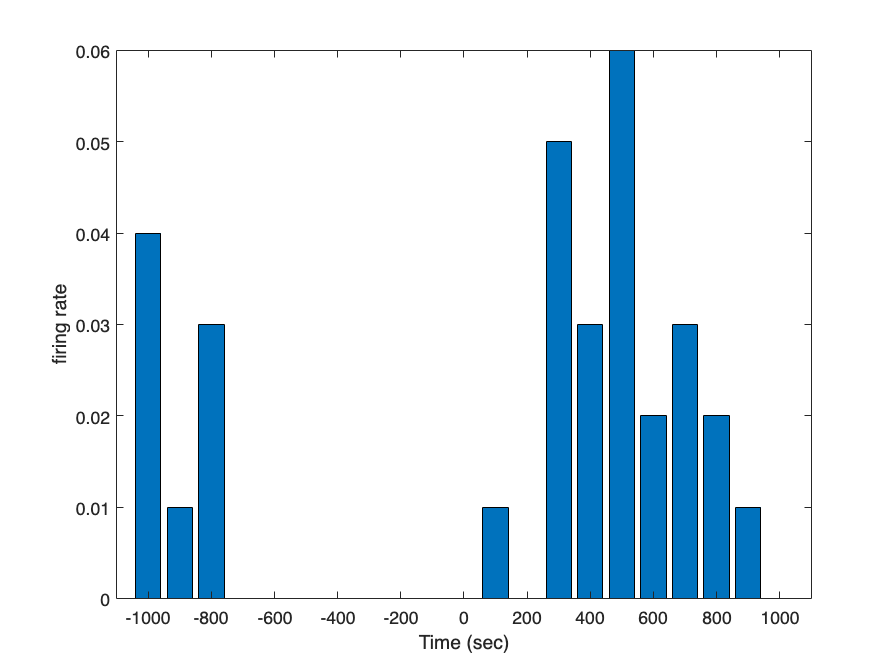

figure
bar(edges,psth); %Plot PSTH as a bar graph 
xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (sec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

지금까지의 코드를 한 단락으로 정리하면 다음과 같습니다.

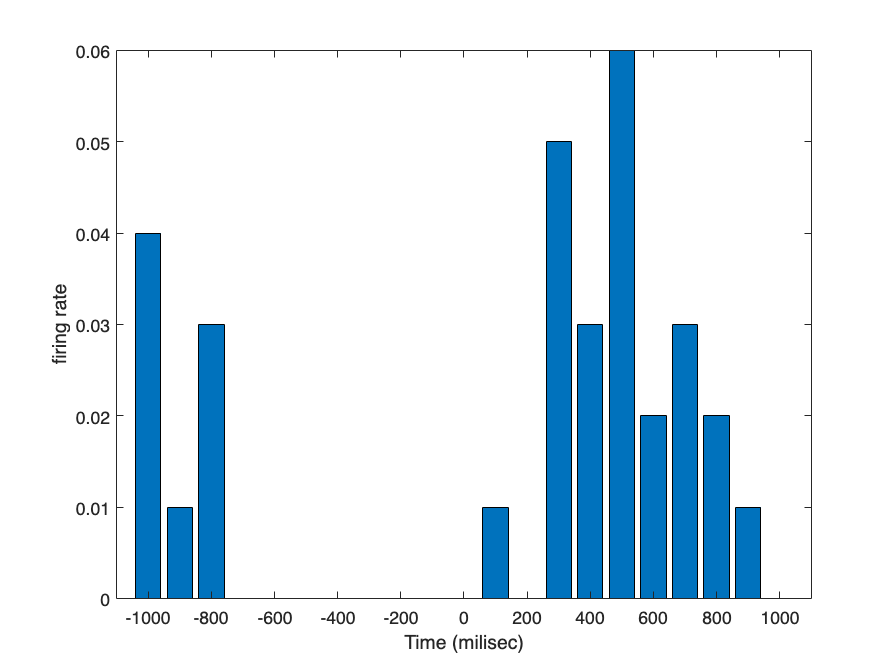

% 0.1. cutoff spikes
data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 2*1e-5; %cutoff
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean); %apply the boolean to get selected spikes

% 0.2. into miliseconds
data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000; %milisecond 단위

% 0.3. Peri-Stiumulus
data1msPS = data1SelectedMs - 1*1000;

% 1. edges
max(data1msPS);
min(data1msPS);
edges = [-1000: 100: 1000]; %시작점 : 구간길이 : 끝점
psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

%2. histc
psth = psth + histc(data1msPS,edges);
psth = psth / 100; %firing rate

%3. bar
figure
bar(edges,psth); %Plot PSTH as a bar graph 
xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (milisec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

## (2) 여러 trial average하기

Data 1.csv와 Data 2.csv 가 같은 source의 서로 다른 trial이라고 가정하고, for loop를 이용해 averageing해 보겠습니다.

두 데이터의 차이점이 두 개 있어서, 이를 보정해 주어야 합니다.

-  Data 2.csv는 시작점이 1.2초 쯤인 반면 저희가 Data 1.csv는 0초에 시작했다고 가정했다는 점

- 두 번째는 Data2.csv가 훨씬 긴 시간동안 측정되었다는 점.

그런데, 두 번째 차이점은 보정해 줄 필요가 없습니다. histc함수가 어차피 주어진 bin에 들어가지 않는 범위의 값은 count하지 않기 때문입니다.

이 두 차이점은, 실제로 두 데이터가 같은 source의 서로 다른 trial이었다면 발생하지 않았을 것입니다. 따라서 실제로 averaging을 할 때는 위 문제를 신경쓰지 않아도 됩니다.

먼저 data1.csv를 위에서 했던 것과 똑같이 전처리합니다.

%%Data 1.csv

% 0.1. cutoff spikes
data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 2*1e-5; 
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean);

% 0.2. into miliseconds
data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000; %milisecond 단위

% 0.3. Peri-Stiumulus
data1msPS = data1SelectedMs - 1*1000

data1msPS =  -992.0685 -979.0609 -935.5964 -908.3122 -862.9442 -758.2487 -733.8198 -713.1980  144.6701  300.4442  307.1066  316.9416  340.4188  371.8274  405.1396  436.2310  469.5431  500.9518  503.4898  510.4695  533.9467  565.6726  598.6675  632.2970  696.7005  730.0127  761.4213  794.4162  825.8249  890.5457  923.5406


이제 Data 2.csv 를 처리합니다.  spike가 초반에 별로 발생하지 않아서, 1.2초를 0초으로 바꾸는 변환을 해도 Data 1.csv의 spike 분포 시간 구간과 맞지 않습니다. 적당히 30초 정도를 0초로 바꾸겠습니다.

%%Data 2.csv

% 0.1. cutoff spikes
data2SpikesMax = max(data2.spikeWaveforms, [], 2); %max for each row
data2SelectedIdxBoolean = data2SpikesMax > 2*1e-5; 
data2SelectedTimestamp = data2.spikeTimestamps(data2SelectedIdxBoolean);

% 0.2. into miliseconds
data2SelectedMs = (data2.startTime + data2SelectedTimestamp / data2.sf) * 1000; %milisecond 단위

%0.2.1. 시작점 바꾸기
data2SelectedMs = data2SelectedMs - (30 * 1000);


% 0.3. Peri-Stiumulus
data2msPS = data2SelectedMs - 1*1000

data2msPS = 1.0e+04 *

   -2.6291   -2.6275   -2.6258   -2.6241   -2.6225   -2.6208   -2.6191   -2.6175   -2.6158   -2.6141   -2.6125   -2.6108   -2.6093   -2.6076   -2.6059   -2.6057   -2.6046   -2.6043   -2.6040   -2.6037   -2.6029   -2.6026   -2.6023   -2.6020   -2.6014   -2.6011   -2.6009   -2.6007   -2.6004   -2.6000   -2.5997   -2.5995   -2.5990   -2.5987   -2.5983   -2.5981   -2.5978   -2.5976   -2.5973   -2.5970   -2.5967   -2.5964   -2.5961   -2.5957   -2.5954   -2.5950   -2.5948   -2.5945   -2.5940   -2.5937


이제 PSTH를 그립니다. for loop를 쓰려면 일단 data1msPS와 data2msPS를 묶어야 하는데, 책에 나온 데로 struct를 사용합니다.

dataBundle = struct("times", {data1msPS, data2msPS})

dataBundle = 다음 필드를 포함한 1×2 struct 배열:
    times


dataBundle(1).times % data1msPS가 나옴을 확인

ans =  -992.0685 -979.0609 -935.5964 -908.3122 -862.9442 -758.2487 -733.8198 -713.1980  144.6701  300.4442  307.1066  316.9416  340.4188  371.8274  405.1396  436.2310  469.5431  500.9518  503.4898  510.4695  533.9467  565.6726  598.6675  632.2970  696.7005  730.0127  761.4213  794.4162  825.8249  890.5457  923.5406


dataBundle(2).times % data2msPS가 나옴을 확인

ans = 1.0e+04 *

   -2.6291   -2.6275   -2.6258   -2.6241   -2.6225   -2.6208   -2.6191   -2.6175   -2.6158   -2.6141   -2.6125   -2.6108   -2.6093   -2.6076   -2.6059   -2.6057   -2.6046   -2.6043   -2.6040   -2.6037   -2.6029   -2.6026   -2.6023   -2.6020   -2.6014   -2.6011   -2.6009   -2.6007   -2.6004   -2.6000   -2.5997   -2.5995   -2.5990   -2.5987   -2.5983   -2.5981   -2.5978   -2.5976   -2.5973   -2.5970   -2.5967   -2.5964   -2.5961   -2.5957   -2.5954   -2.5950   -2.5948   -2.5945   -2.5940   -2.5937


averaging을 하므로, firing rate를 추가로 trial 개수로 나눠 주어야 합니다.

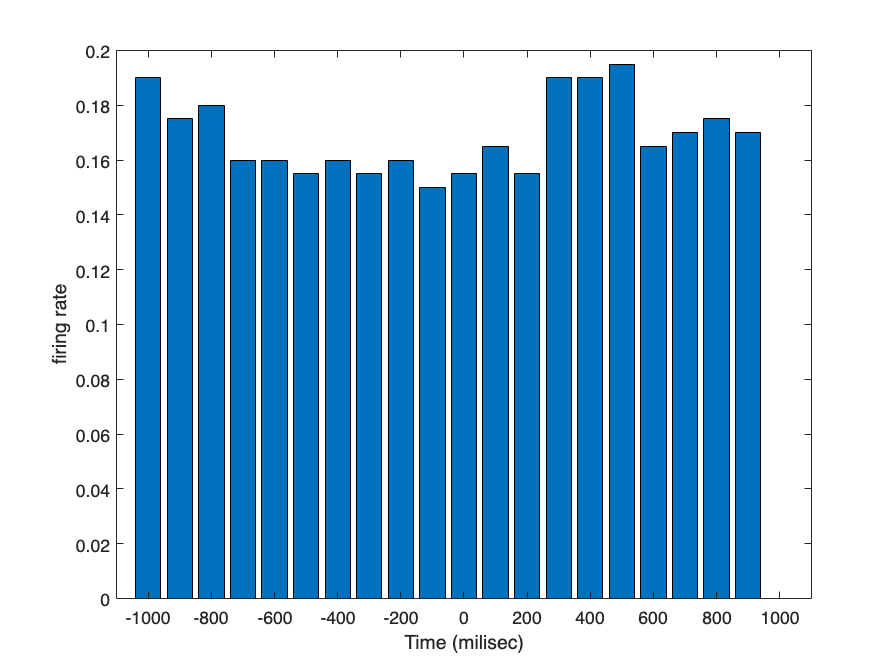

% 1. edges

edges = [-1000: 100: 1000]; %시작점 : 구간길이 : 끝점
psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

%2. histc with for loop
for j  = 1:2
    psth = psth + histc(dataBundle(j).times,edges);
end
psth = (psth / 100) / 2; %averaging

%3. bar
figure
bar(edges,psth); %Plot PSTH as a bar graph 
xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (milisec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

## (3) Raster plot

raster plot은  https://github.com/CyBrainOrg의 코드에도 그리는 코드가 나와있습니다. 하지만 보내 주신 책에 있는 코드가 더 직관적이고, PSTH와 함께 그리기 더 편하게 되어 있어서, 해당 코드를 사용하겠습니다.

### (3.1) raster plot 하나

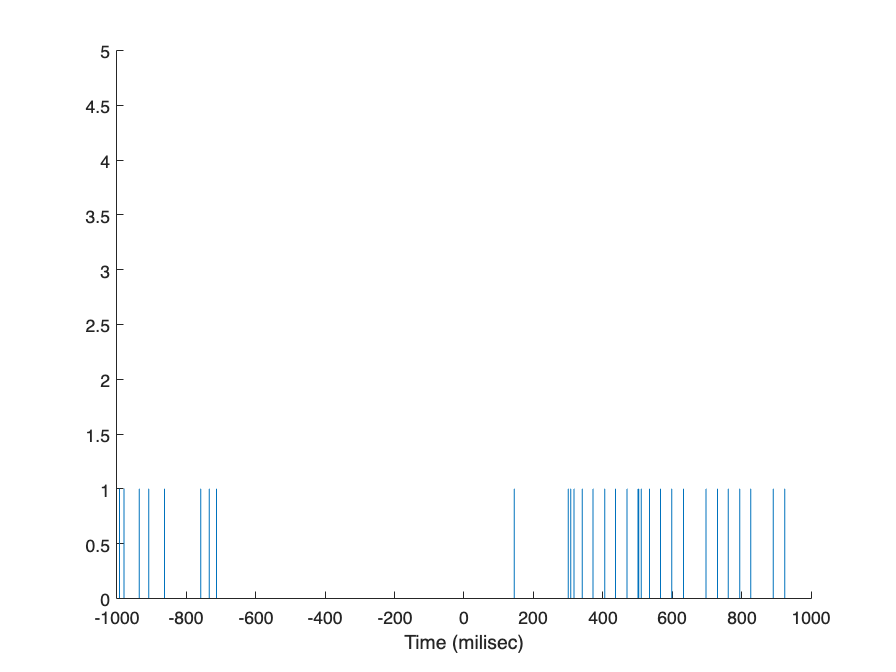

figure %새로운 plot을 시작 
hold on % hold off할 때까지, 모든 plot을 겹쳐서 그림. 각 tick을 한 figure에 담기 위한 세팅.

%Data 1.csv의 raster plot
for i = 1:length(data1msPS) %data2msPS의 첫 원소부터 마지막 원소까지
    line([data1msPS(i) data1msPS(i)], [0 1])  % (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다.
end
hold off %이제 plot을 겹쳐 그리지 않음
ylim([0 5])
xlabel("Time (milisec)")

### (3.2) raster plot 두 개 

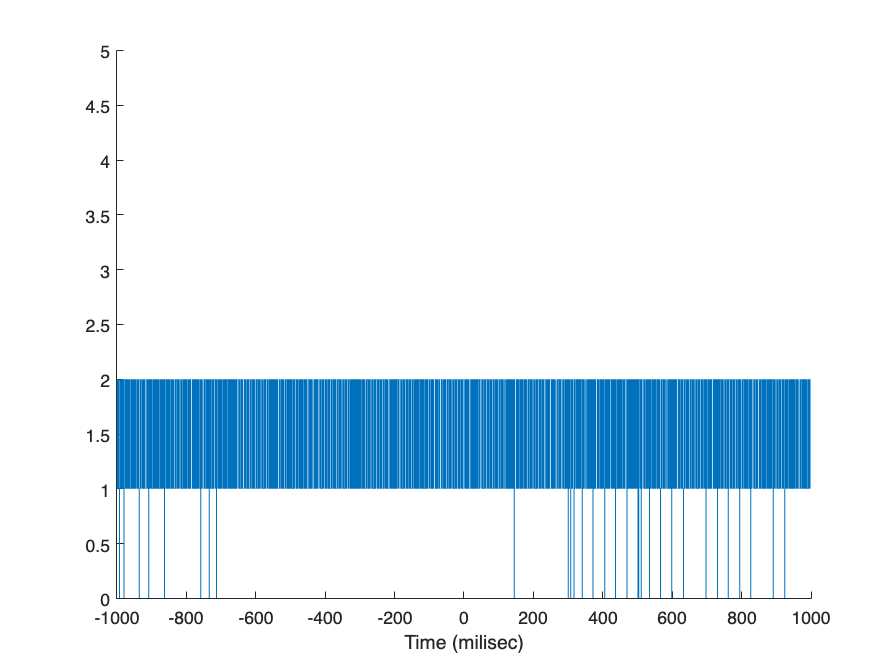

figure %새로운 plot을 시작 
hold on % hold off할 때까지, 모든 plot을 겹쳐서 그림

%Data 1.csv의 raster plot
for i = 1:length(data1msPS) %data2msPS의 첫 원소부터 마지막 원소까지 (Loop through each spike time )
    line([data1msPS(i) data1msPS(i)], [0 1])  % 두 점 (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다(Create a tick mark at x = t1(i) with a height of 1).
end

%Data 2.csv의 raster plot

for j = 1:length(data2msPS)
    line([data2msPS(j) data2msPS(j)], [1 2]) 
end 

hold off %이제 plot을 겹쳐 그리지 않음
xlim([-1000, 1000]) 
ylim([0 5]) %Reformat y-axis for legibility
xlabel("Time (milisec)") %Label x-axis 

## (3.3) raster + PSTH

hold on을 잘 활용하면 raster plot과 PSTH를 같이 그릴 수 있습니다. firing rate는 1 이하의 값이므로 raster plot 이 너무 크게 나오지 않게 조절해 주기만 하면 됩니다.

또는 그냥 두 개 figure를 x축만 통일한 후 위아래로 잘 붙여도 됩니다.

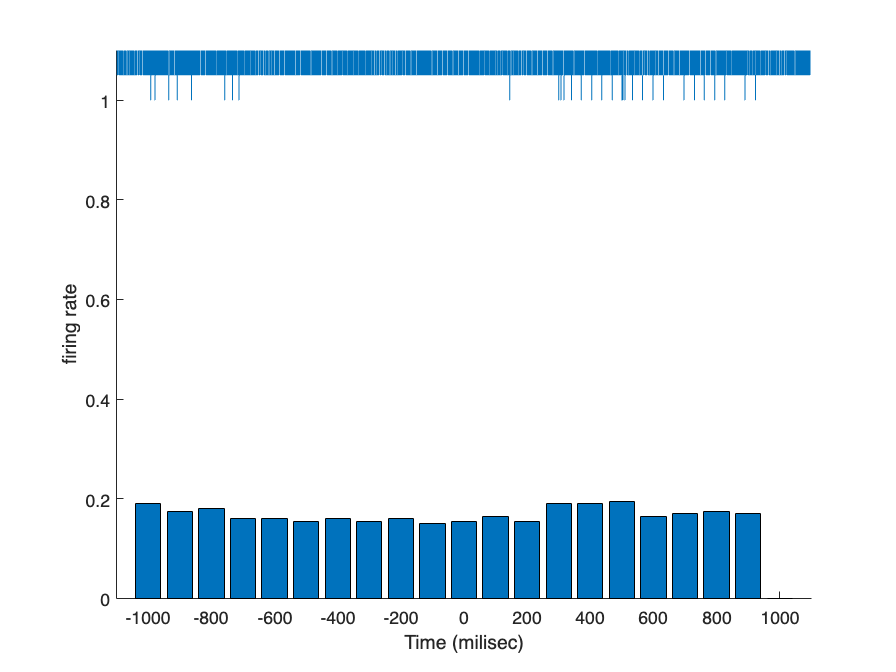

%PSTH

% 1. edges

edges = [-1000: 100: 1000]; %시작점 : 구간길이 : 끝점
psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

%2. histc with for loop
for j  = 1:2
    psth = psth + histc(dataBundle(j).times,edges);
end
psth = (psth / 100) / 2; %averaging

%3. bar
figure
hold on

bar(edges,psth); %Plot PSTH as a bar graph 


%raster
%Data 1.csv의 raster plot
for i = 1:length(data1msPS) %data2msPS의 첫 원소부터 마지막 원소까지 (Loop through each spike time )
    line([data1msPS(i) data1msPS(i)], [1, 1.05])  % 두 점 (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다(Create a tick mark at x = t1(i) with a height of 1).
end

%Data 2.csv의 raster plot

for j = 1:length(data2msPS)
    line([data2msPS(j) data2msPS(j)], [1.05, 1.1]) 
end 

hold off %이제 plot을 겹쳐 그리지 않음

ylim([0 1.1]) %Reformat y-axis for legibility

xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (milisec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

# **2022년 4월 작업내용**

작업내역

- threshold 설정: spike detection(section 2.2) and spike amplitude filtering(section 2.3)

- 구간별 spike 개수 count 및 그래프

- 구간별 firing rate count 및 그래프

- heatmap

- 일렬 포맷 데이터 읽어오기(아직 못함)

## **1. 데이터 불러오기**

(데이터를 불러오는 방법에 대한 전반적인 설명은` reading_method_guide.mlx `파일에 있습니다)

보내주신 `23-channel2.xlsx ``파일로 작업하였습니다. 해당 파일은 여러 채널의 데이터를 담고 있지만 반복측정 데이터는 아니어서, 제가 임의로 한 채널의 데이터를 10등분 한 다음 섞어서 다른 데이터인 것처럼 만들었습니다. `

#### `channelReader `object

`여러 채널이 있는 데이터를 불러오려면 channelReader `object를` 먼저 만들어야 합니다. channelReader 파일을 먼저 통째로 읽어온 다음에, 거기서 개별 `channel `데이터를 가져와서 channel `object를` 만들고 이 channel `object를` 통해서 데이터 분석을 수행합니다.`

`아래에서 3개의 똑같은 파일을 불러오는 channelReader `object를` 만들었습니다. 하지만 이는 반복 측정 데이터가 없어서 어쩔 수 없이 한 행동이고, 원래는 각 channelReader 다른 파일을 불러오거나(반복측정 데이터가 여러 파일로 이루어져 있을 때) 한 reader가 한 파일을 불러오게 됩니다(반복측정 데이터가 한 파일에 다 들어있을 때)`

`channelReader의 readMultiChannelFile 메소드로 파일을 읽어들입니다(이 메소드에 대한 자세한 설명은 reading_method_guide.mlx `파일에 있습니다)`. filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate순으로 파라미터를 입력합니다. 이 섹션에서는 이 메소드로 ``23-channel2.xlsx`` 파일을 불러오는 방법만 간략히 설명합니다.`

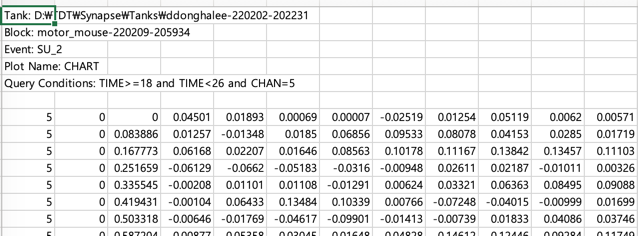

- `filename: 파일 이름입니다. 상대경로 혹은 절대경로를 사용할 수 있습니다. 아래 예제에서는 상대경로를 사용했습니다. 확장자까지 다 써 주어야 합니다.`

- `channelColumnIdx: 파일 내에서 채널 정보가 몇 번째 열에 있는지 써줍니다. 이 파일은 첫 번째 열에 있으니 1을 넣습니다.`

- `timeColumnIdx: 시간 정보가 몇 번쨰 열에 있는지 써줍니다. 이 파일은 세 번째 열에 있으니 3을 넣습니다.`

- `startRowIdx: 관측치 데이터가 몇 번째 행에서 시작하는지 써 줍니다. 이 파일은 7번째 행부터 시작하니 7을 넣습니다.`

- `startColIdx: 관측치 데이터가 몇 번째 열에서 시작하는지 써 줍니다. 이 파일은 4번째 열부터 시작하니 4를 넣습니다.`

- `sampleRate: 파일에 시간 정보가 있어서, 자동으로 sampling frequency(Hz)를 계산하므로 이 값은 nan을 넣습니다.`

`channelReader가 readMultiChannelFile로 파일을 불러오면, 해당 파일에 있는 채널 번호를 출력합니다.`

% 첫 번째 파일을 불러오는 reader object 생성
reader_interval_1 = channelReader();
tic 
%                                             filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader_interval_1.readMultiChannelFile("./data/23-channel2.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 5 channels: 

ans =      3     5     6     7     9


% 두 번째 파일을 불러오는 reader object 생성
reader_interval_2 = channelReader();
tic 
%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader_interval_2.readMultiChannelFile("./data/23-channel2.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 5 channels: 

ans =      3     5     6     7     9


% 세 번째 파일을 불러오는 reader object 생성

reader_interval_3 = channelReader();
tic 
%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader_interval_3.readMultiChannelFile("./data/23-channel2.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 5 channels: 

ans =      3     5     6     7     9


#### `channel `object

이제 각 `reader에서 5번 채널만 가져와 channel `object로` 만들겠습니다. organoind, month는 그냥 관리를 위해 붙이는 번호입니다. channel 항목에만 5를 넣어 주면 됩니다. 성공적으로 불러오면 해당 채널에 대한 정보를 출력합니다.`

% readSingleChannelFromFile: 원하는 channel 하나만 가져오기
%                                                  organoid, channel, month 
ch5_rep1 = reader_interval_1.readSingleChannelFromFile(1, 5, 1);

channel number = 5
sampling rate = 24413.999990Hz
starts at 0.000000, ends at 17.532154, duration = 17.532154
number of timestamps = 428031



ch5_rep2 = reader_interval_2.readSingleChannelFromFile(1, 5, 1);

channel number = 5
sampling rate = 24413.999990Hz
starts at 0.000000, ends at 17.532154, duration = 17.532154
number of timestamps = 428031



ch5_rep3 = reader_interval_3.readSingleChannelFromFile(1, 5, 1);

channel number = 5
sampling rate = 24413.999990Hz
starts at 0.000000, ends at 17.532154, duration = 17.532154
number of timestamps = 428031



### (실제 분석에서는 생략) 데이터 섞어서 반복측정 자료인 것처럼 만들기

ch5_rep2, ch5_rep3의 경우, 원래는 반복측정 데이터여야 하지만 여기서는 불가피하게 같은 파일을 불러왔으므로 제가 인위적으로 데이터를 조작하여 다른 데이터로 만들겠습니다. 제가 만든 `shuffle` 메소드를 이용해 데이터를 n개 구간으로 쪼갠 뒤 랜덤으로 구간들을 섞어서 다른 데이터로 만듭니다.

아래 plot은 섞은 결과를 표시한 것입니다. 신호의 모양이 달라진 것을 볼 수 있습니다.

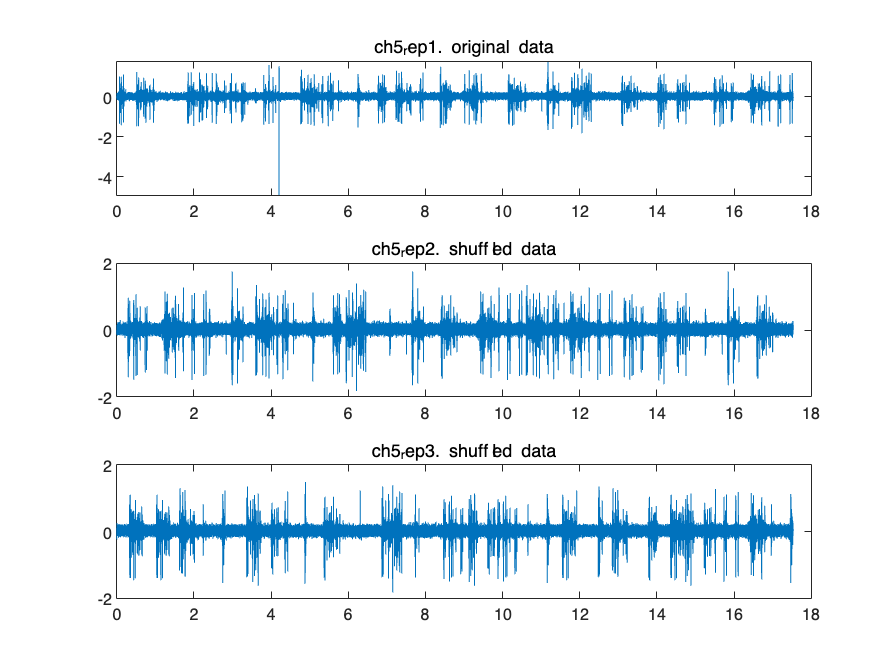

ch5_rep2.shuffle(15); %15개 구간으로 쪼개서 섞음
ch5_rep3.shuffle(25); %25개 구간으로 쪼개서 섞음

figure;
subplot(3,1,1);
plot(ch5_rep1.t, ch5_rep1.raw);
title("ch5_rep1. original data")

subplot(3,1,2);
plot(ch5_rep2.t, ch5_rep2.raw);
title("ch5_rep2. shuffled data");

subplot(3,1,3);
plot(ch5_rep3.t, ch5_rep3.raw);
title("ch5_rep3. shuffled data")

## **2. 데이터 전처리**

#### **2.1. bandpass filter 적용**

ch5_rep1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
ch5_rep2.bandPass([300,3000]); %apply bandpass filter 300-3000hz
ch5_rep3.bandPass([300,3000]); %apply bandpass filter 300-3000hz

#### **2.2. Spike detection**

- 모든 시간 범위에서 standard deviation을 계산한 다음 그 값을 기준으로  spike를 찾음

- 일단 전 구간에서 동일한 기준(> `thres *` standrad deviation)으로 spike를 찾은 다음 개별 구간에 들어가는 spike의 개수를 샐 것임

**paramter 3개**

- `thres`: spike 분류 기준. 5를 입력하면 평균+5표준편차 밖의 값을 spike로 분류.  첫 번째 input 값(아래 코드에서는 5)을 바꿔주면 **전 구간에서 동일한** thres 값이 적용됨

- `preTime`: spike waveform의 spike 앞쪽 너비. spike로 판정된 점 앞뒤로 얼마만큼을 해당 spike의 구간으로 볼 것인지를 결정. milisecond 단위 (reference code에서는 2)

- `postTime`: spike waveform의 spike 뒷쪽 너비. spike로 판정된 점 앞뒤로 얼마만큼을 해당 spike의 구간으로 볼 것인지를 결정.  milisecond 단위 (reference code에서는 2)

                   %thres, preTime, postTime
ch5_rep1.detectSpikes(5,2,2);

number of spikes found : 504


ch5_rep2.detectSpikes(5,2,2);

number of spikes found : 531


ch5_rep3.detectSpikes(5,2,2);

number of spikes found : 501


ch5_rep2, ch5_rep3는 waveform의 모양이 바뀌면서 spike의 개수가 달라졌습니다.

#### **2.3. ****특정 ****amplitude( ****예 ****: 60 ㎶) ****이상의 ****spike만 골라내기**

하나의 threshold 값을 전 시간 영역에 적용합니다.

channel object에서 spike detection을 한 결과는 두 attribute에 저장됩니다.

- `.spikeTimestamps`: 1d array. spike가 발견된 timestamp를 저장. (https://github.com/CyBrainOrg의 spike detection algorithm의 output)

- `.spikeWaveforms`: 2d array. nrow = nSpikes, ncol = waveform 길이(timestamp 단위). spike 앞뒤를 정해진 길이로 잘라 얻은 waveform을 각 row에 저장.

예를 들어 60 ㎶ 이상의 spike만 골라내려면

- 먼저 `.spikeWaveforms의` 각 row의 max값을 취한 뒤 60 이상인 row의 index만 고릅니다.

- `.spikeTimestamps에서 그 `index에` 해당하는 원소만 골라서 저장합니다.`

`제가 파일의 측정 단위를 잘 모르기 때문에, 임의의 값 0.7을 cutoff로 사용하겠습니다.`

`ch5_rep1에 대해 적용:`

%%%% threshold는 아래 값을 변경하면 됩니다. %%%%
%%%% 단위는 raw data의 측정 단위를 따릅니다. %%%%
thres_amplitude = 0.7;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%아래 코드를 다른 object에 적용하려면 첫 번째 줄과 두 번째 줄에서는 두 번, 세 번째 줄에서는 세 번 이름을 바꿔주어야 합니다.
ch5_rep1_SpikesMax = max(ch5_rep1.spikeWaveforms, [], 2); %.spikeWaveforms의 각 row의 max를 계산합니다. 각 row가 spike 하나에 해당하므로, 각 spike의 max amplitude를 계산하는 것입니다.
ch5_rep1_SelectedIdxBoolean = ch5_rep1_SpikesMax > thres_amplitude; % cutoff 값을 적용합니다. (true, true, false, true, false,...)와 같은 결과가 나옵니다. 이것을 이용해 max amplitude가 cutoff 값 이상인 spike의 timestamp를 걸러냅니다.
ch5_rep1_SelectedTimestamp = ch5_rep1.spikeTimestamps(ch5_rep1_SelectedIdxBoolean); % apply the boolean and get the selected spikes
length(ch5_rep1_SelectedTimestamp) % 걸러낸 후 spike개 몇 개 남았는지를 봅니다.

ans = 115

`ch5_rep2에 대해 적용:`

%%%% threshold는 아래 값을 변경하면 됩니다. %%%%
%%%% 단위는 raw data의 측정 단위를 따릅니다. %%%%
thres_amplitude = 0.7;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ch5_rep2_SpikesMax = max(ch5_rep2.spikeWaveforms, [], 2); %.spikeWaveforms의 각 row의 max를 계산합니다. 각 row가 spike 하나에 해당하므로, 각 spike의 max amplitude를 계산하는 것입니다.
ch5_rep2_SelectedIdxBoolean = ch5_rep2_SpikesMax > thres_amplitude; % cutoff 값을 적용합니다. (true, true, false, true, false,...)와 같은 결과가 나옵니다. 이것을 이용해 max amplitude가 cutoff 값 이상인 spike의 timestamp를 걸러냅니다.
ch5_rep2_SelectedTimestamp = ch5_rep2.spikeTimestamps(ch5_rep2_SelectedIdxBoolean); % apply the boolean and get the selected spikes
length(ch5_rep2_SelectedTimestamp) % 걸러낸 후 spike개 몇 개 남았는지를 봅니다.

ans = 125

`ch5_rep3에 대해 적용:`

%%%% threshold는 아래 값을 변경하면 됩니다. %%%%
%%%% 단위는 raw data의 측정 단위를 따릅니다. %%%%
thres_amplitude = 0.7;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ch5_rep3_SpikesMax = max(ch5_rep3.spikeWaveforms, [], 2); %.spikeWaveforms의 각 row의 max를 계산합니다. 각 row가 spike 하나에 해당하므로, 각 spike의 max amplitude를 계산하는 것입니다.
ch5_rep3_SelectedIdxBoolean = ch5_rep3_SpikesMax > thres_amplitude; % cutoff 값을 적용합니다. (true, true, false, true, false,...)와 같은 결과가 나옵니다. 이것을 이용해 max amplitude가 cutoff 값 이상인 spike의 timestamp를 걸러냅니다.
ch5_rep3_SelectedTimestamp = ch5_rep3.spikeTimestamps(ch5_rep3_SelectedIdxBoolean); % apply the boolean and get the selected spikes
length(ch5_rep3_SelectedTimestamp) % 걸러낸 후 spike개 몇 개 남았는지를 봅니다.

ans = 107

### 2.4. (mili)second 단위로 변환

저희가 레퍼런스로 삼은 https://github.com/CyBrainOrg의 코드에서는 spike detection의 output을 timestamp로 내므로, 이를 milisecond 단위로 바꿔 줍니다.

아래 두 값들은 코드에서 사용된 값들이고, 별도로 계산할 필요 없이 `channel 오브젝트가 자동으로 계산한 것을 .xxx 형식을 통해 불러와서 쓰는 것입니다. 이 두 값들을 이용해서 `miliscecond` 단위 값을 계산합니다.`

- **.startTime** : 데이터의 측정 시작점

- **.sf** : sample rate(Hz). timestamp를 이 값으로 나눠주면 second 단위의 표현이 되고, 여기에 1000을 곱하면 milisecond 단위의 표현이 됨.

`ch5_rep1에 대해 적용:`

ch5_rep1_SelectedMs = (ch5_rep1.startTime + ch5_rep1_SelectedTimestamp / ch5_rep1.sf) * 1000 %milisecond 단위

ch5_rep1_SelectedMs = 1.0e+04 *

    0.0069    0.0114    0.0116    0.0176    0.0515    0.0562    0.0567    0.0695    0.0740    0.0950    0.1848    0.1850    0.1931    0.1933    0.2140    0.2171    0.2323    0.2472    0.2476    0.2580    0.2589    0.2972    0.3813    0.3947    0.4050    0.4052    0.4207    0.4769    0.4771    0.4788    0.4867    0.4954    0.4956    0.5035    0.5115    0.5118    0.5338    0.5480    0.5537    0.5539    0.6251    0.6255    0.6785    0.6788    0.6894    0.6941    0.7250    0.7252    0.7316    0.7377


`ch5_rep2에 대해 적용:`

ch5_rep2_SelectedMs = (ch5_rep2.startTime + ch5_rep2_SelectedTimestamp / ch5_rep2.sf) * 1000 %milisecond 단위

ch5_rep2_SelectedMs = 1.0e+04 *

    0.0297    0.0332    0.0431    0.0434    0.0440    0.0443    0.0496    0.1250    0.1283    0.1308    0.1515    0.1517    0.1521    0.1728    0.1948    0.2014    0.2255    0.2314    0.2980    0.2982    0.2989    0.2993    0.2995    0.3126    0.3600    0.3602    0.3619    0.3698    0.3785    0.3787    0.3866    0.3947    0.3949    0.4169    0.4311    0.4368    0.4370    0.5082    0.5086    0.5616    0.5620    0.5725    0.5772    0.5944    0.5948    0.6019    0.6021    0.6106    0.6118    0.6215


`ch5_rep3에 대해 적용:`

ch5_rep3_SelectedMs = (ch5_rep3.startTime + ch5_rep3_SelectedTimestamp / ch5_rep3.sf) * 1000 %milisecond 단위

ch5_rep3_SelectedMs = 1.0e+04 *

    0.0341    0.0345    0.0347    0.1042    0.1046    0.1048    0.1640    0.1642    0.1706    0.1766    0.1774    0.1777    0.2745    0.2748    0.3366    0.3368    0.3385    0.3465    0.3527    0.3567    0.3585    0.3587    0.3664    0.4022    0.4369    0.4429    0.4878    0.4888    0.4890    0.5389    0.5391    0.5397    0.5616    0.5618    0.6872    0.6874    0.6892    0.6971    0.7041    0.7053    0.7150    0.7257    0.7319    0.7333    0.7389    0.7743    0.8479    0.8513    0.8613    0.8615


## **3. 자극 전, 중, 후로 구분된 히스토그램**

- 먼저 spike 개수를 정해진 구간 안으로 분류해서 넣어야 합니다(binning). 이 과정은 edges, histc로 요약할 수 있습니다. 그리고 평균과 표준편차를 계산합니다.

- bar 함수로 그래프를 그리고 standard error를 세로선으로 표시합니다.

### 3.1. Binning

### 3.1.1. edges

time을 작은 구간(bin)으로 쪼개는 기준이 되는 값들입니다. 

이전에 히스토그램을 그릴 때는 `구간길이`를 정해서 여러 개의 구간으로 나눴지만, 

이번에는 자극을 준 시점을 명시하여 구간을 3개로 나눠야 합니다. 자극 중 구간의 시작 시간과 끝 시간을 명시합니다.

위 섹션의 예제에서는 peri-stimulus를 구현하기 위해 자극을 준 시점의 t값을 모든 t값에서 빼 주었고, 이 때문에 `data1SelectedMs가 data1msPS으로 바뀌었었지만, 이번에는 굳이 그렇게 하지 않고 시간 변수를 그대로 두겠습니다.`

시간 구간은 1d array로 표현하는데, `histc` 함수에서 이 array를 bin으로 바꾸는 방식이 특이합니다.

예를 들어 `edges` = [1,2,3,4]일 때, `histc` 함수는 [1,2), [2,3), [3,4), {4}로 변환합니다. 즉, 3개의 right-open interval과 하나의 singleton으로 변환합니다. 따라서 측정 끝점 값은 넉넉하게 크게 잡는 것이 좋습니다.

초 단위로 작성한 다음 1000을 곱해 밀리초 단위로 만들었습니다.

edges = [0, 10 , 13, 18]* 1000 %측정 시작점 : 자극시작 : 자극 끝: 측정 끝점보다 약간 큰 값

edges =            0       10000       13000       18000


### 1.2. histc

이제 histc함수를 이용해서, 0에서 준비한 데이터를 1에서 만든 bin에 차곡차곡 분리해서 넣고 개수를 셉니다.

결과를 보면 마지막 값이 0이 나오는데, 이는 t가 singleton 집합 {18000}에 속하는 데이터 수를 샌 것입니다. 정확히 18000밀리초 시점에 측정된 데이터가 없다면 0이 나오는 것이 맞습니다.

구간을 많이 나눌 때는 히스토그램에 막대가 많으므로 저런 값을 그냥 두었지만, 이번에는 막대가 3개밖에 없으므로, 그림을 깔끔하게 하기 위해 마지막 값은 지우겠습니다.

또한 y축이 # of spikes인 것과 firing rate인 것을 모두 plot해 보기 위해   nspikes_per_bin을 bin size로 나눈 데이터도 만들겠습니다.. bin size가 각 구간별로 다르므로 원소별 나누기인 `./`를 사용합니다.

ch5_rep1_binned = histc(ch5_rep1_SelectedMs,edges) % ch5_rep1의 spikes를 binning해서 더함

ch5_rep1_binned =     65    20    30     0


ch5_rep2_binned = histc(ch5_rep2_SelectedMs,edges) % ch5_rep2의 spikes를 binning해서 더함

ch5_rep2_binned =     72    28    25     0


ch5_rep3_binned = histc(ch5_rep3_SelectedMs,edges) % ch5_rep3의 spikes를 binning해서 더함

ch5_rep3_binned =     61    21    25     0


binning한 결과를 row로 삼아 아래로 쌓습니다. 이는 표준편차를 쉽게 계산하기 위해서입니다. matlab에서 [ ] 안에서 ;로 구분하면 다음 row로 넘어갑니다.

binned_stack = [ch5_rep1_binned; ch5_rep2_binned; ch5_rep3_binned]

binned_stack =     65    20    30     0
    72    28    25     0
    61    21    25     0


binned_stack = binned_stack(:, 1:(end-1)) %마지막 원소가 0이라 의미 없으므로 그냥 없애기

binned_stack =     65    20    30
    72    28    25
    61    21    25


2d array(=행렬)에서 mean과 std를 계산하면 기본적으로 column별로 계산하므로 bin별 계산이 됩니다.

nspikes_per_bin_mean = mean(binned_stack)

nspikes_per_bin_mean =    66.0000   23.0000   26.6667


nspikes_per_bin_std = std(binned_stack)

nspikes_per_bin_std =     5.5678    4.3589    2.8868


firing rate를 계산합니다. spike 개수를 구간 길이(시간)으로 나눠 주면 됩니다. array 나누기 array를 원소별로 하려면 ./ 를 사용합니다.

bin_size = diff(edges) % diff는 연속된 두 원소의 차를 계산함. 따라서 diff(edges)는 bin size가 됨.

bin_size =        10000        3000        5000


fireRate_per_bin_mean = nspikes_per_bin_mean ./ bin_size %firing rate

fireRate_per_bin_mean =     0.0066    0.0077    0.0053


fireRate_per_bin_std = std(binned_stack ./ bin_size) % row 별로 firing rate를 계산한 다음에 (행렬 A를 row vector v로 ./하면 행렬의 각 row를 v로 ./합니다) column 별로 standard deviation을 계산                                       

fireRate_per_bin_std =     0.0006    0.0015    0.0006


### 3.2. bar

막대그래프를 그려주는 bar 함수를 이용합니다. 이전과 다르게, x축에서 시간을 그대로 사용하지 않고 범주형 데이터를 사용합니다(categorical 함수 사용).

standard deviation을 표시하기 위해 `errorbars` 함수를 사용합니다

데이터를 제 임의로 shuffle해서 그런지 standard deviation이 매우 크게 나옵니다.

**구간별 firing rate**

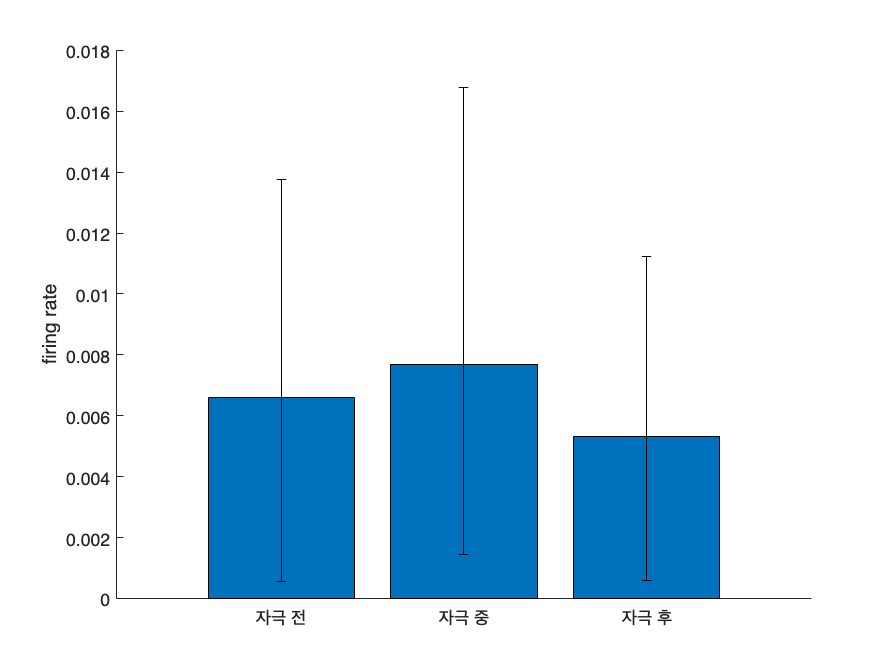

x = categorical({'자극 전','자극 중','자극 후'});
errhigh = fireRate_per_bin_mean + fireRate_per_bin_std;
errlow = fireRate_per_bin_mean - fireRate_per_bin_std;
figure;
hold on;
bar(x, fireRate_per_bin_mean); %막대그래프. x값, y값 순서

er = errorbar(x,fireRate_per_bin_mean,errlow,errhigh); % 표준편차 표시. x값, y값, -표준편차, +표준편차 순서
er.Color = [0 0 0]; % error bar의 색깔을 검은색으로 설정
er.LineStyle = 'none'; % 막대들 사이를 가로로 잇는 선을 보이지 않게 설정
hold off;

ylabel('firing rate'); %Label y-axis

**구간별 number of spikes**

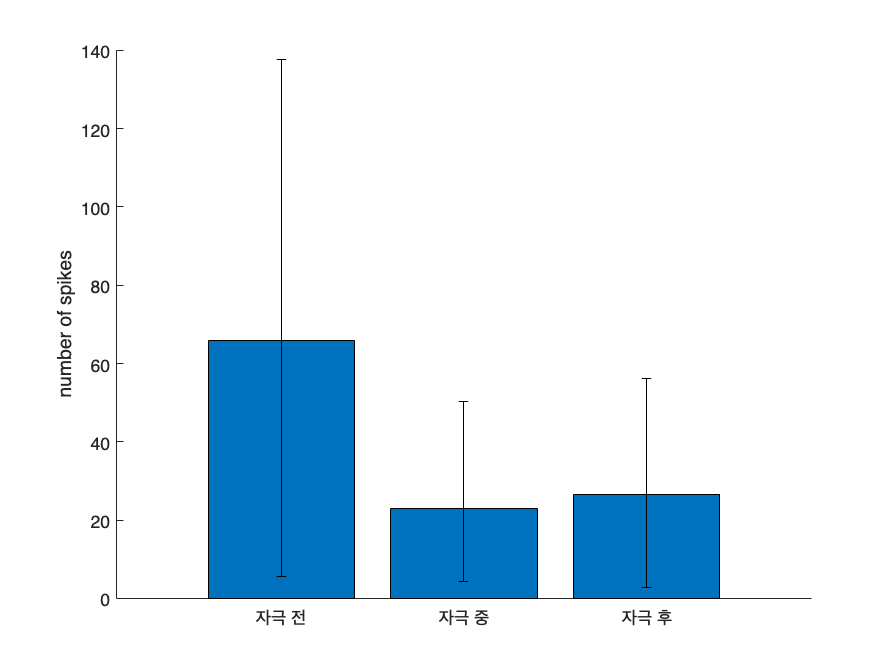

x = categorical({'자극 전','자극 중','자극 후'});
errhigh = nspikes_per_bin_mean + nspikes_per_bin_std;
errlow = nspikes_per_bin_mean - nspikes_per_bin_std;
figure;
hold on;
bar(x, nspikes_per_bin_mean); %막대그래프. x값, y값 순서

er = errorbar(x,nspikes_per_bin_mean,errlow,errhigh); % 표준편차 표시. x값, y값, -표준편차, +표준편차 순서
er.Color = [0 0 0]; % error bar의 색깔을 검은색으로 설정
er.LineStyle = 'none'; % 막대들 사이를 가로로 잇는 선을 보이지 않게 설정
hold off;
ylabel('number of spikes'); %Label y-axis

## **4. heatmap**

가로는 구간, 세로는 데이터(채널, replication 등...)인 것으로 이해하였습니다.

heatmap은 행렬을 색깔로 표현한 것입니다. 따라서 어떤 데이터라도 행렬의 형태로 데이터를 만들 수만 있다면 heatmap으로 만들 수 있습니다.

heatmap 함수 정보: https://kr.mathworks.com/help/matlab/ref/heatmap.html

세로를 데이터로 정했으므로, nspikes_per_bin_mean나 fireRate_per_bin_mean를 세로로 쌓은 뒤 heatmap을 그리면 됩니다.

먼저 위에서 그린 세 칸 짜리 bar graph를 그린 데이터를 가지고 heatmap을 만들어 보겠습니다.

colormap 관련 정보: https://kr.mathworks.com/help/matlab/ref/colormap.html

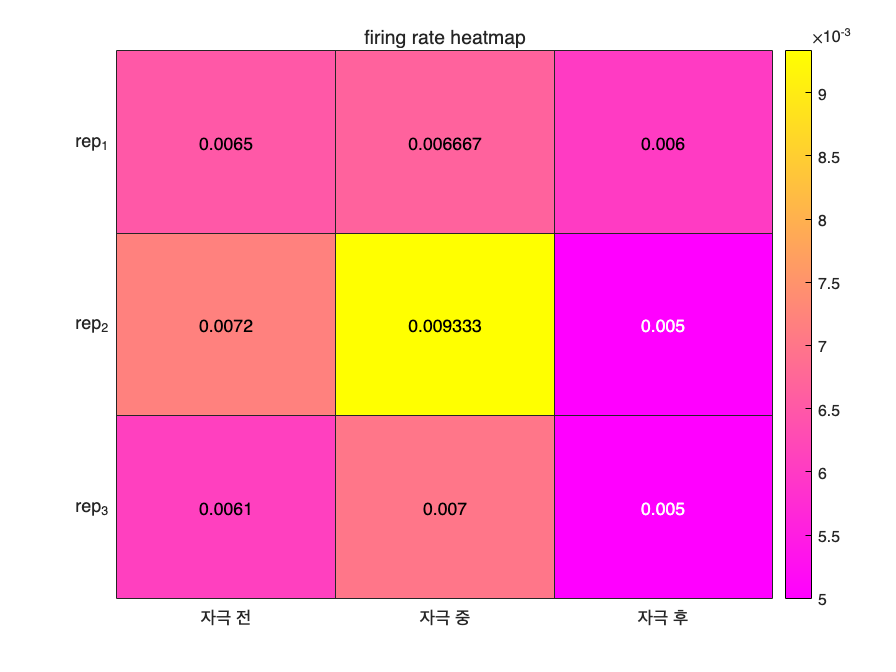

firing_rate_matrix = binned_stack ./ bin_size; % bin별 spike 개수 행렬을 bin size로 나눠 firing rate matrix를 만듦

xvalues = {'자극 전','자극 중','자극 후'};
yvalues = {'rep_1','rep_2','rep_3'}; %y축 데이터. 위에서부터 나열
       %x축 레이블, y축 레이블, 데이터 행렬,                컬러맵

figure;       
heatmap(xvalues, yvalues, firing_rate_matrix, 'Colormap', spring)
title("firing rate heatmap")

이번에는 시간 구간을 1초 단위로 나눠서 그려보겠습니다.

edges_many = [0: 1000: 18000] %1000밀리초 단위로 binning

edges_many =            0        1000        2000        3000        4000        5000        6000        7000        8000        9000       10000       11000       12000       13000       14000       15000       16000       17000       18000


bin_size_many = diff(edges_many)

bin_size_many =         1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000        1000


ch5_rep1_binned_many = histc(ch5_rep1_SelectedMs,edges_many) % ch5_rep1의 spikes를 binning해서 더함

ch5_rep1_binned_many =     10     4     8     2     9     7     6     8     3     8     3    12     5     5     7     7     7     4     0


ch5_rep2_binned_many = histc(ch5_rep2_SelectedMs,edges_many) % ch5_rep2의 spikes를 binning해서 더함

ch5_rep2_binned_many =      7     8     8    10     4     8     9     6     5     7    13     7     8     7     7     6     5     0     0


ch5_rep3_binned_many = histc(ch5_rep3_SelectedMs,edges_many) % ch5_rep3의 spikes를 binning해서 더함

ch5_rep3_binned_many =      3     9     2     9     6     5     4     8     7     8     5     6    10     3     8     4     8     2     0


binning한 결과를 row로 삼아 아래로 쌓습니다. 이는 표준편차를 쉽게 계산하기 위해서입니다. matlab에서 [ ] 안에서 ;로 구분하면 다음 row로 넘어갑니다.

binned_stack_many = [ch5_rep1_binned_many; ch5_rep2_binned_many; ch5_rep3_binned_many]

binned_stack_many =     10     4     8     2     9     7     6     8     3     8     3    12     5     5     7     7     7     4     0
     7     8     8    10     4     8     9     6     5     7    13     7     8     7     7     6     5     0     0
     3     9     2     9     6     5     4     8     7     8     5     6    10     3     8     4     8     2     0


binned_stack_many = binned_stack_many(:, 1:(end-1)); %마지막 원소가 0이라 의미 없으므로 그냥 없애기
firing_rate_matrix_many = binned_stack_many ./ bin_size_many % bin별 spike 개수 행렬을 bin size로 나눠 firing rate matrix를 만듦

firing_rate_matrix_many =     0.0100    0.0040    0.0080    0.0020    0.0090    0.0070    0.0060    0.0080    0.0030    0.0080    0.0030    0.0120    0.0050    0.0050    0.0070    0.0070    0.0070    0.0040
    0.0070    0.0080    0.0080    0.0100    0.0040    0.0080    0.0090    0.0060    0.0050    0.0070    0.0130    0.0070    0.0080    0.0070    0.0070    0.0060    0.0050         0
    0.0030    0.0090    0.0020    0.0090    0.0060    0.0050    0.0040    0.0080    0.0070    0.0080    0.0050    0.0060    0.0100    0.0030    0.0080    0.0040    0.0080    0.0020


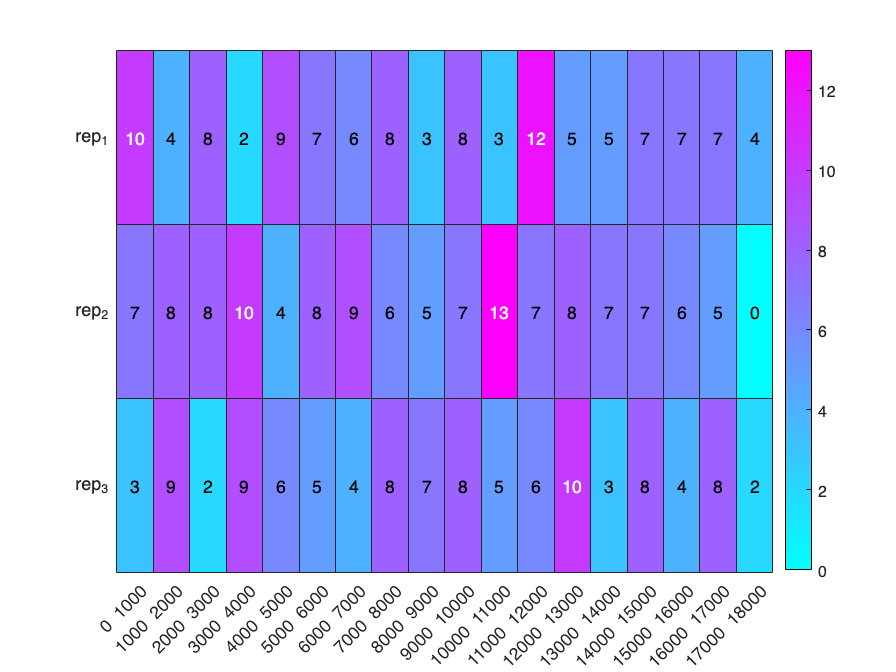

xvalues_many = {};
for i = 1 : (length(edges_many) - 1);
 xvalues_many{i} = num2str([edges_many(i), edges_many(i+1)]); % 구간을 array로 만든 다음 string으로 바꿔 레이블을 만듦
end

yvalues_many = {'rep_1','rep_2','rep_3'}; %y축 데이터. 위에서부터 나열
       %x축 레이블, y축 레이블, 데이터 행렬,                컬러맵
heatmap(xvalues_many, yvalues_many, binned_stack_many, 'Colormap', cool)

# 2022년 6월 27일 작업내용

일렬로 된 데이터 읽어오기

raw_data = readmatrix("/Users/mac/GitHub/neurosignal-matlab/data/17.xlsx"); %문종민의 컴퓨터에서 작업할 때

size_of_data = size(raw_data); % 데이터 행과 열 개수
number_of_timestamp = size_of_data(1)-1; % 열 개수 - 1 = 측정 timestamp 개수


%시간 벡터 저장 및 sampling frequency 계산
tVector = raw_data(:,1); %시간 벡터를 따로 저장
sampleRateUsed = number_of_timestamp/(tVector(end) - tVector(1)); %sample rate 계산. 전체 시간을 관측치 개수로 나눔
size(tVector)

## potential column C 읽어오기


%%%%%%
%원하는 컬럼을 지정해서 한개의 week만 불러옴
column_potential_1 = 3;
xVector = raw_data(:,column_potential_1+1); % i번째 채널 데이터는 1+1번째 행에 있음 %결국엔 여기서 몇번째 컬럼인지를 기술해 주면 됩니다.
size(xVector)
xVector = xVector(~isnan(xVector)); % time 열에 맞춰 데이터를 불러오기 때문에, 빈칸이 NaN으로 들어올 수 있습니다. 이 부분을 제거해 줍니다.
size(xVector)

% 만약 potential column 길이가 time column길이보다 짧을 경우, 알맞게 t vector를 잘라 줍니다

ans =      1048575           1


tVector = tVector(1:length(xVector));
size(tVector)

ans =      1048575           1



[xResampled, tResampled] = resample(xVector, tVector, sampleRateUsed, 'spline'); %시간간격을 등간격으로 resample 및 interpolation 실행
                                                    %organoid, channelNum,

ans =      1048575           1


                 % 마지막 3개는 단순히 관리를 위한 번호: organoid number, channel number, month number
potential_1 = channel(xResampled, tResampled, sampleRateUsed, 1, 1, 1);

## potential column D 읽어오기


column_potential_2 = 4;
xVector = raw_data(:,column_potential_1+1); % i번째 채널 데이터는 1+1번째 행에 있음 %결국엔 여기서 몇번째 컬럼인지를 기술해 주면 됩니다.
size(xVector)

channel number = 1
sampling rate = 24414.000001Hz
starts at 0.000000, ends at 42.949701, duration = 42.949701
number of timestamps = 1048575



xVector = xVector(~isnan(xVector)); % time 열에 맞춰 데이터를 불러오기 때문에, 빈칸이 NaN으로 들어올 수 있습니다. 이 부분을 제거해 줍니다.
size(xVector)

% 만약 potential column 길이가 time column길이보다 짧을 경우, 알맞게 t vector를 잘라 줍니다
tVector = tVector(1:length(xVector));
size(tVector)

ans =      1048575           1



[xResampled, tResampled] = resample(xVector, tVector, sampleRateUsed, 'spline'); %시간간격을 등간격으로 resample 및 interpolation 실행

ans =      1048575           1


                                                    %organoid, channelNum,
                 % 마지막 3개는 단순히 관리를 위한 번호: organoid number, channel number, month number
potential_2 = channel(xResampled, tResampled, sampleRateUsed, 1, 2, 1);

ans =      1048575           1


channel number = 2
sampling rate = 24414.000001Hz
starts at 0.000000, ends at 42.949701, duration = 42.949701
number of timestamps = 1048575



### 이제 potential_1, potential_2를 가지고 4월 작업 내용의 **2. 데이터 전처리부터 진행하면 됩니다(ch5_rep1 대신에 **potential_1, potential_2를 넣으면 됩니다)